% script to read RTV data from HFRnet TDS 
% data url from OPeNDap page
url='http://hfrnet-tds.ucsd.edu/thredds/dodsC/HFR/USWC/6km/hourly/RTV/HFRADAR_US_West_Coast_6km_Resolution_Hourly_RTV_best.ncd';%

## display info on netcdf variables

TDSinfo=ncinfo(url);
TDSinfo.Variables.Name

ans = 'lat'

ans = 'lon'

ans = 'time'

ans = 'time_run'

ans = 'site_lat'

ans = 'site_lon'

ans = 'site_code'

ans = 'site_netCode'

ans = 'procParams'

ans = 'time_offset'

ans = 'u'

ans = 'v'

ans = 'DOPx'

ans = 'DOPy'

ncdisp(url,'u')

Source:
           http://hfrnet-tds.ucsd.edu/thredds/dodsC/HFR/USWC/6km/hourly/RTV/HFRADAR_US_West_Coast_6km_Resolution_Hourly_RTV_best.ncd
Format:
           classic
Dimensions:
           lon  = 234
           lat  = 367
           time = 69440
Variables:
    u
           Size:       234x367x69440
           Dimensions: lon,lat,time
           Datatype:   single
           Attributes:
                       units               = 'm s-1'
                       long_name           = 'surface_eastward_sea_water_velocity'
                       standard_name       = 'surface_eastward_sea_water_velocity'
                       ancillary_variables = 'DOPx'
                       _ChunkSizes         = [1  367  234]
                       coordinates         = 'time_run time lat lon '


ncdisp(url,'v','min')

Source:
           http://hfrnet-tds.ucsd.edu/thredds/dodsC/HFR/USWC/6km/hourly/RTV/HFRADAR_US_West_Coast_6km_Resolution_Hourly_RTV_best.ncd
Format:
           classic
Variables:
    v
           Size:       234x367x69440
           Dimensions: lon,lat,time
           Datatype:   single


## Read in time

timebase=erase(ncreadatt(url,'time','units'),'hours since ');
time=ncread(url,'time')/24 + datenum(timebase,'yyyy-mm-dd HH:MM:SS');

% time index for latest observation usually has less data
% choose 3 hour old obs
mytime=length(time)-3;

% view date string of start and end time
datestr(double(time([1 end])))

ans = 2×20 char array
    '01-Oct-2011 00:00:00'
    '04-Sep-2019 17:00:00'


## Read in lat and lon of grid

% retrieve lat and lon variables
lat=ncread(url,'lat');
lon=ncread(url,'lon');

## Subset grid

% set geographical limits
lat_max=35;
lat_min=32;

lon_max=-116;
lon_min=-120;

lon_j = find(lon >= lon_min & lon <= lon_max);
lat_j = find(lat >= lat_min & lat <= lat_max);


## Read in Data

u=ncread(url, 'u', [lon_j(1) lat_j(1) mytime], [lon_j(end)-lon_j(1)+1 lat_j(end)-lat_j(1)+1 1]);
v=ncread(url, 'v', [lon_j(1) lat_j(1) mytime], [lon_j(end)-lon_j(1)+1 lat_j(end)-lat_j(1)+1 1]);


## Plot U&V

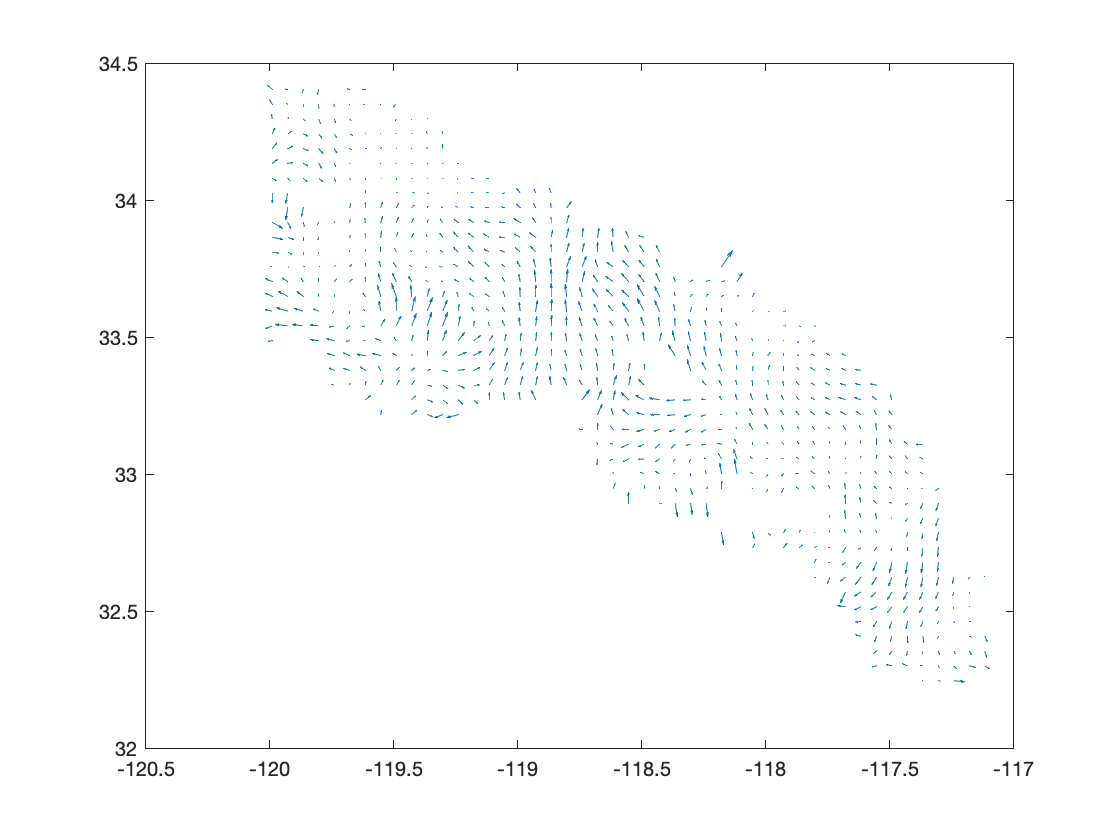

[LN,LT]=meshgrid(lon(lon_j),lat(lat_j));
quiver(LN,LT,u',v');